clear all
clc
clf
close
f1 = figure;
f2 = figure;

% Constant Parameter
R = 44;
Lg = 120;
mass = 0.36;
format longG

% Data
Water2 = [0.106, 0.081, 0.05, 0.019, -0.052, -0.083, -0.112, -0.134]

Water2 =                      0.106                     0.081                      0.05                     0.019                    -0.052                    -0.083                    -0.112                    -0.134


Water4 = [0.18, 0.135, 0.079, 0.023, -0.092, -0.148, -0.195, -0.234]

Water4 =                       0.18                     0.135                     0.079                     0.023                    -0.092                    -0.148                    -0.195                    -0.234


Oil2 = [0.105, 0.081, 0.049, 0.017, -0.051, -0.082, -0.111, -0.132]

Oil2 =                      0.105                     0.081                     0.049                     0.017                    -0.051                    -0.082                    -0.111                    -0.132


Oil4 = [0.178, 0.133, 0.079, 0.023, -0.092, -0.145, -0.191, -0.231]

Oil4 =                      0.178                     0.133                     0.079                     0.023                    -0.092                    -0.145                    -0.191                    -0.231




% Variable
h = 0:0.1:300;
theta = deg2rad(10);
cutoff = 0;
for k1 = 1:length(h)
    if h(k1) > 2*R*sin(theta)
        cutoff = k1
        break
    end
end

cutoff =    154



grid on
% Formulas
figure(f1)
title('Liquid height vs Torque Error for 400g Oil')
xlabel("Height (mm)")
ylabel("Error between experimental and calculated torque (Nm)")
for i = 10:10:40
    theta = deg2rad(i);
    for k1 = 1:length(h)
        if h(k1) > 2*R*sin(theta)
            cutoff = k1
            break
        end
    end
    V = pi*R^2*(h/cos(theta)-2*R*tan(theta))+pi*R^3*tan(theta);
    XL = (pi*R^4)./(4*V)*tan(theta);
    YL = (1./V).*((R*tan(theta)+h/cos(theta)-2*R*tan(theta)).^2*(1/2*pi*R^2)+(tan(theta)^2*(1/8*pi*R^4)));
    A = Lg*sin(theta);
    X = XL*cos(theta)+YL*sin(theta)-Lg*sin(theta);
    tz = mass*9.81*X/1000;
    hold on
    plot(h(cutoff:end),(Water4(i/10+4)-tz(cutoff:end)))
end

cutoff =    154


cutoff =    302


cutoff =    441


cutoff =    567


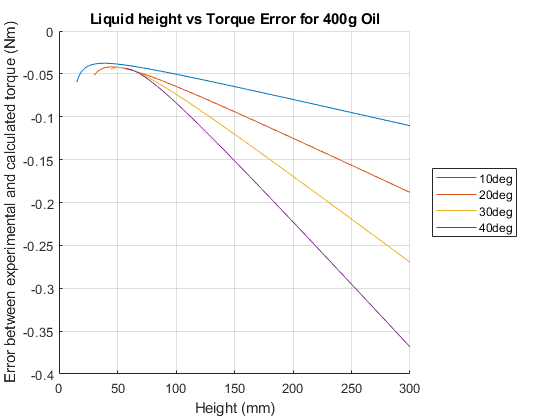

legend("10deg","20deg","30deg","40deg",'Location','eastoutside')
hold off
grid on

figure(f2)
title('Liquid height vs Torque Error for 400g Oil')
xlabel("Height (mm)")
ylabel("Error between experimental and calculated torque (Nm)")
for i = [-10,-20,-30,-40]
    theta = deg2rad(i);
    for k1 = 1:length(h)
        if h(k1) > 2*R*sin(abs(theta))
            cutoff = k1
            break
        end
    end
    V = pi*R^2*(h/cos(theta)-2*R*tan(theta))+pi*R^3*tan(theta);
    XL = (pi*R^4)./(4*V)*tan(theta);
    YL = (1./V).*((R*tan(theta)+h/cos(theta)-2*R*tan(theta)).^2*(1/2*pi*R^2)+(tan(theta)^2*(1/8*pi*R^4)));
    A = Lg*sin(theta);
    X = XL*cos(theta)+YL*sin(theta)-Lg*sin(theta);
    tz = mass*9.81*X/1000;
    hold on
    plot(h(cutoff:end),(Water4(abs(i)/10)-tz(cutoff:end)))
end

cutoff =    154


cutoff =    302


cutoff =    441


cutoff =    567


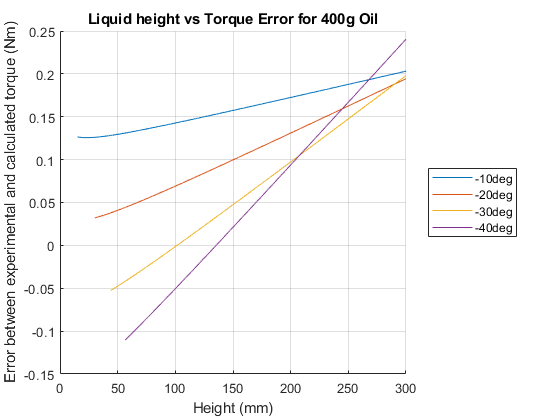

legend("-10deg","-20deg","-30deg","-40deg",'Location','eastoutside')
hold off